# Miami AI demo

## Data Prep

### Dataset creation

% Define the time range
startTime = datetime('now'); % Current time
endTime = startTime + days(3); % 3 days later
timeVector = startTime:hours(3):endTime; % Sampling every 3 hours

% Convert time to hours elapsed since startTime
timeHours = hours(timeVector - startTime);

% Parameters for the temperature model
avgTemp = 22;       % Average temperature (degrees Celsius)
amp = 5;            % Amplitude of temperature variation
dailyPeriod = 24;   % Period of one full day (in hours)
phaseShift = -pi/2; % Phase shift to set the peak temperature around midday

% Generate temperature data following a logical day/night pattern
temperatureData = avgTemp + amp * sin(2*pi*timeHours/dailyPeriod + phaseShift) + randn(size(timeHours))*0.5;

% Create the table with both variables as column vectors
temperatureForecast = table(timeVector', temperatureData', ...
    'VariableNames', {'Time', 'Temperature'});

% Convert to Timetable
TT = table2timetable(temperatureForecast)

TT = 25x1 timetable
            Time            Temperature
    ____________________    ___________

    18-Mar-2025 16:30:01      17.267   
    18-Mar-2025 19:30:01      18.622   
    18-Mar-2025 22:30:01      22.279   
    19-Mar-2025 01:30:01      25.882   
    19-Mar-2025 04:30:01      27.522   
    19-Mar-2025 07:30:01      24.667   
    19-Mar-2025 10:30:01      22.072   
    19-Mar-2025 13:30:01      18.649   
    19-Mar-2025 16:30:01      16.149   
    19-Mar-2025 19:30:01      18.511   
    19-Mar-2025 22:30:01      22.534   
    20-Mar-2025 01:30:01      24.775   
    20-Mar-2025 04:30:01      27.021   
    20-Mar-2025 07:30:01      25.248   
    20-Mar-2025 10:30:01<

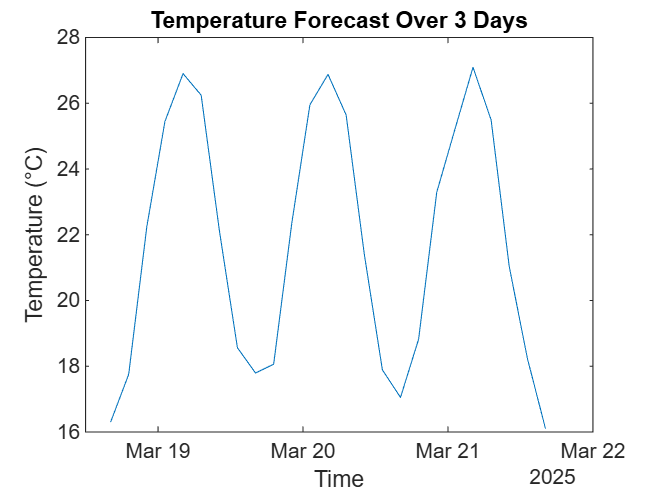

clf
plot(temperatureForecast.Time,temperatureForecast.Temperature)
% Add labels and title to the plot
xlabel('Time');
ylabel('Temperature (°C)');
title('Temperature Forecast Over 3 Days');

### Retime

% Retime timetable
newTimetable = retime(TT,"regular","linear","TimeStep",hours(1))

newTimetable = 74x1 timetable
            Time            Temperature
    ____________________    ___________

    18-Mar-2025 16:00:00      16.231   
    18-Mar-2025 17:00:00      16.716   
    18-Mar-2025 18:00:00      17.201   
    18-Mar-2025 19:00:00      17.686   
    18-Mar-2025 20:00:00      19.042   
    18-Mar-2025 21:00:00      20.538   
    18-Mar-2025 22:00:00      22.035   
    18-Mar-2025 23:00:00      23.163   
    19-Mar-2025 00:00:00       24.23   
    19-Mar-2025 01:00:00      25.298   
    19-Mar-2025 02:00:00      25.864   
    19-Mar-2025 03:00:00      26.349   
    19-Mar-2025 04:00:00      26.834   
    19-Mar-2025 05:00:00      26.714   
    19-Mar-2025

### Smooth

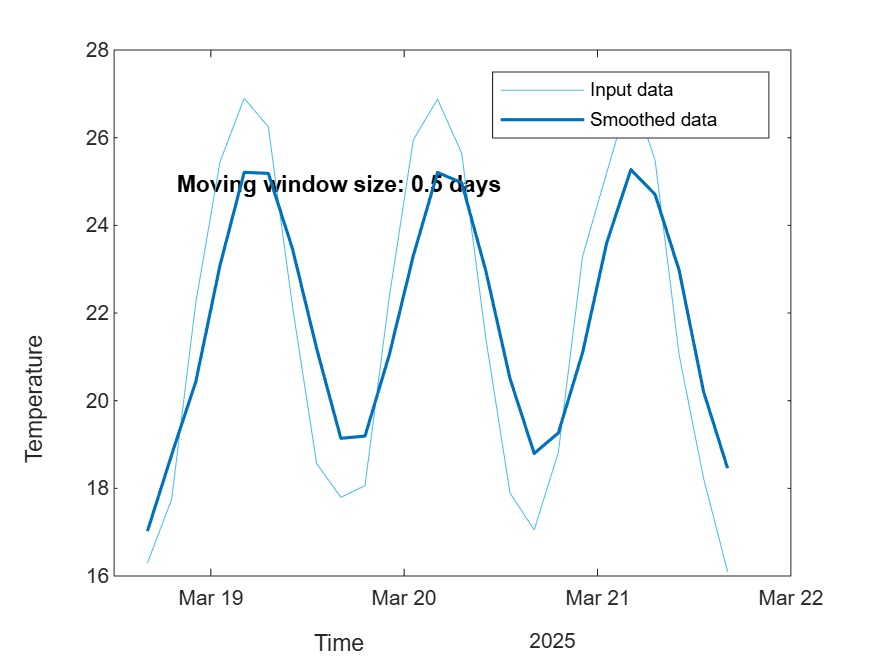

% Smooth input data
[newTable,winSize] = smoothdata(TT,"movmean",days(0.5));

% Display results
figure
plot(TT.Time,TT.Temperature,"SeriesIndex",6,"DisplayName","Input data")
hold on
plot(TT.Time,newTable.Temperature,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize));
legend
ylabel("Temperature")
xlabel("Time")

clear winSize

Go further

edit 1_Data_Analysis/analyze2013stormData.mlx

## Classification

create a weather dataset that can be used for classification

% Define the number of samples
numSamples = 1000;

% Generate synthetic weather data
temperature = randi([0, 40], numSamples, 1); % Temperature in degrees Celsius
humidity = randi([0, 100], numSamples, 1); % Humidity in percentage
windSpeed = randi([0, 20], numSamples, 1); % Wind speed in km/h

% Generate labels based on conditions
labels = strings(numSamples, 1);
for i = 1:numSamples
    if temperature(i) > 30 && humidity(i) < 50
        labels(i) = 'Sunny';
    elseif humidity(i) > 70
        labels(i) = 'Rainy';
    else
        labels(i) = 'Cloudy';
    end
end

% Create a table for the dataset
weatherData = table(temperature, humidity, windSpeed, labels, ...
    'VariableNames', {'Temperature', 'Humidity', 'WindSpeed', 'Condition'});

% Display the first few rows of the dataset
head(weatherData)

Derive test data

testData = removevars(weatherData, "Condition");
writetable(testData,"2_Machine_Learning/testData.csv")

### Training

classificationLearner

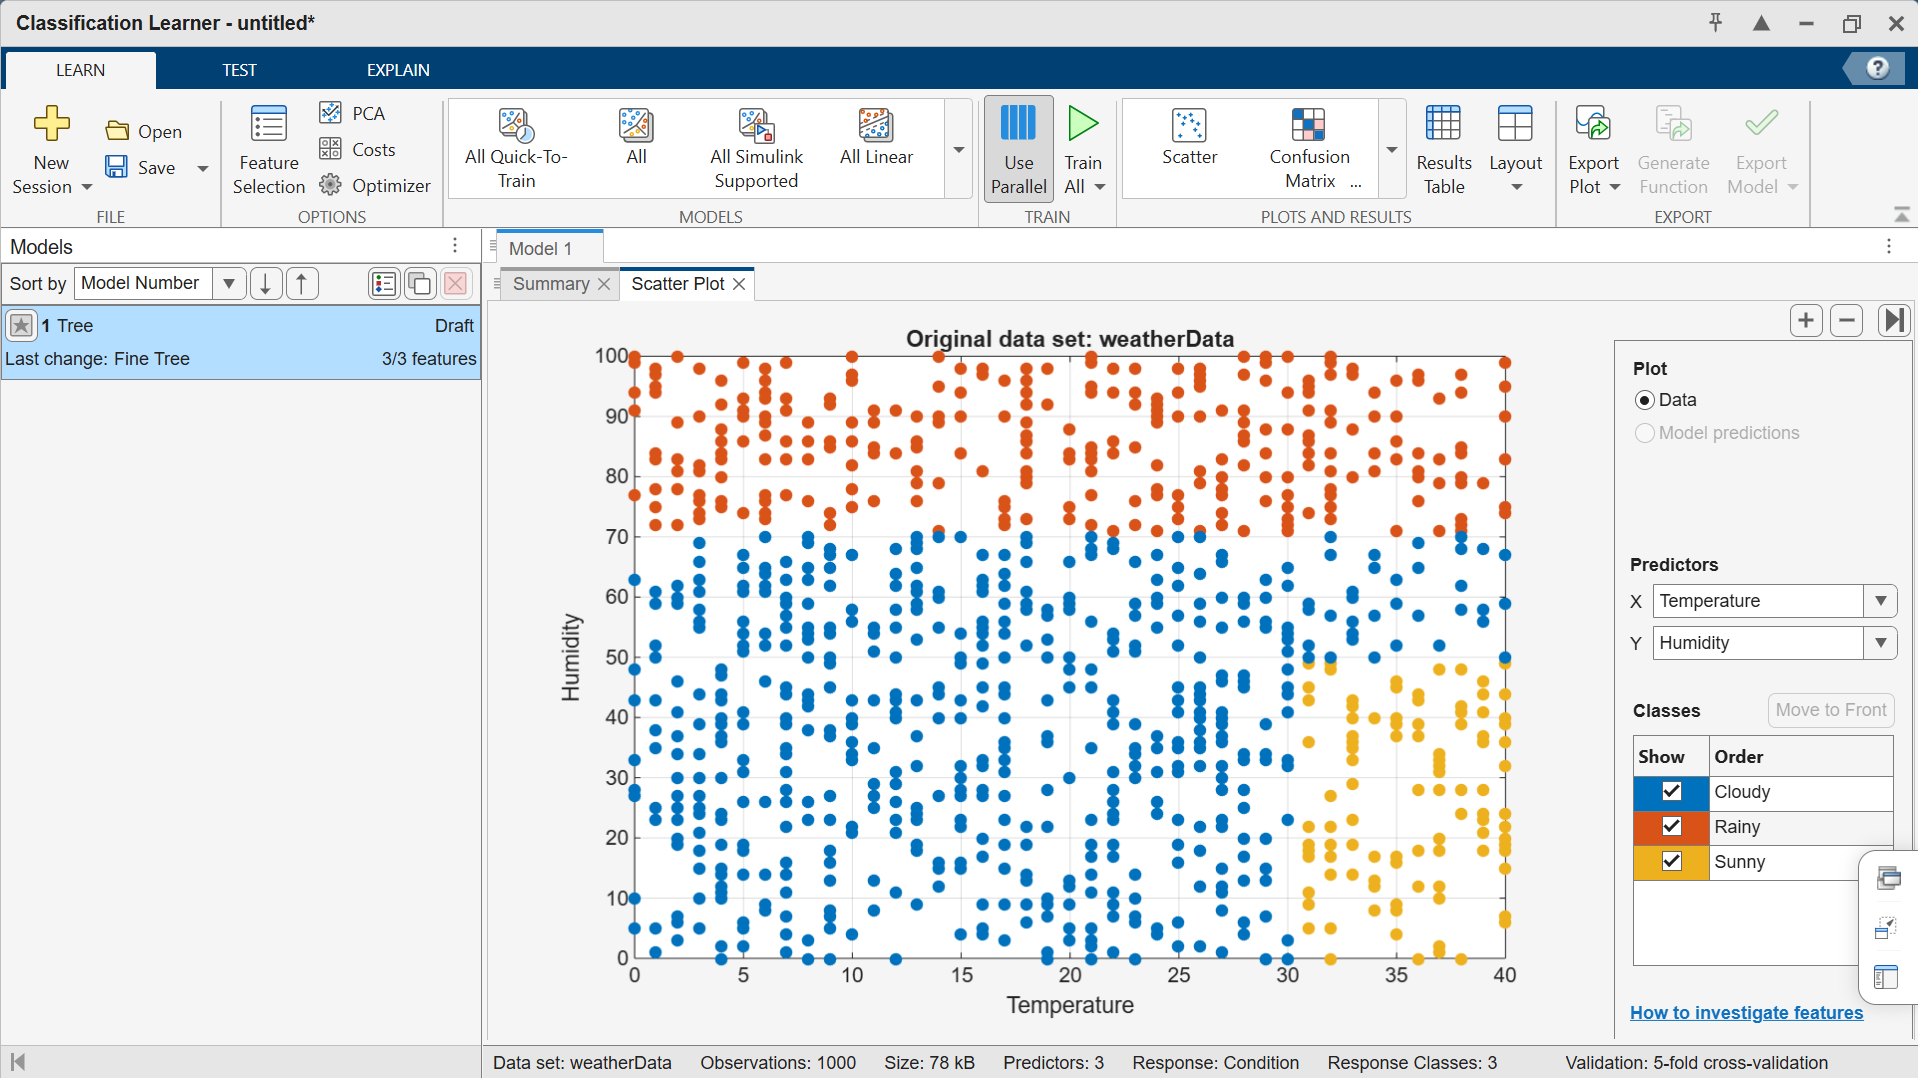

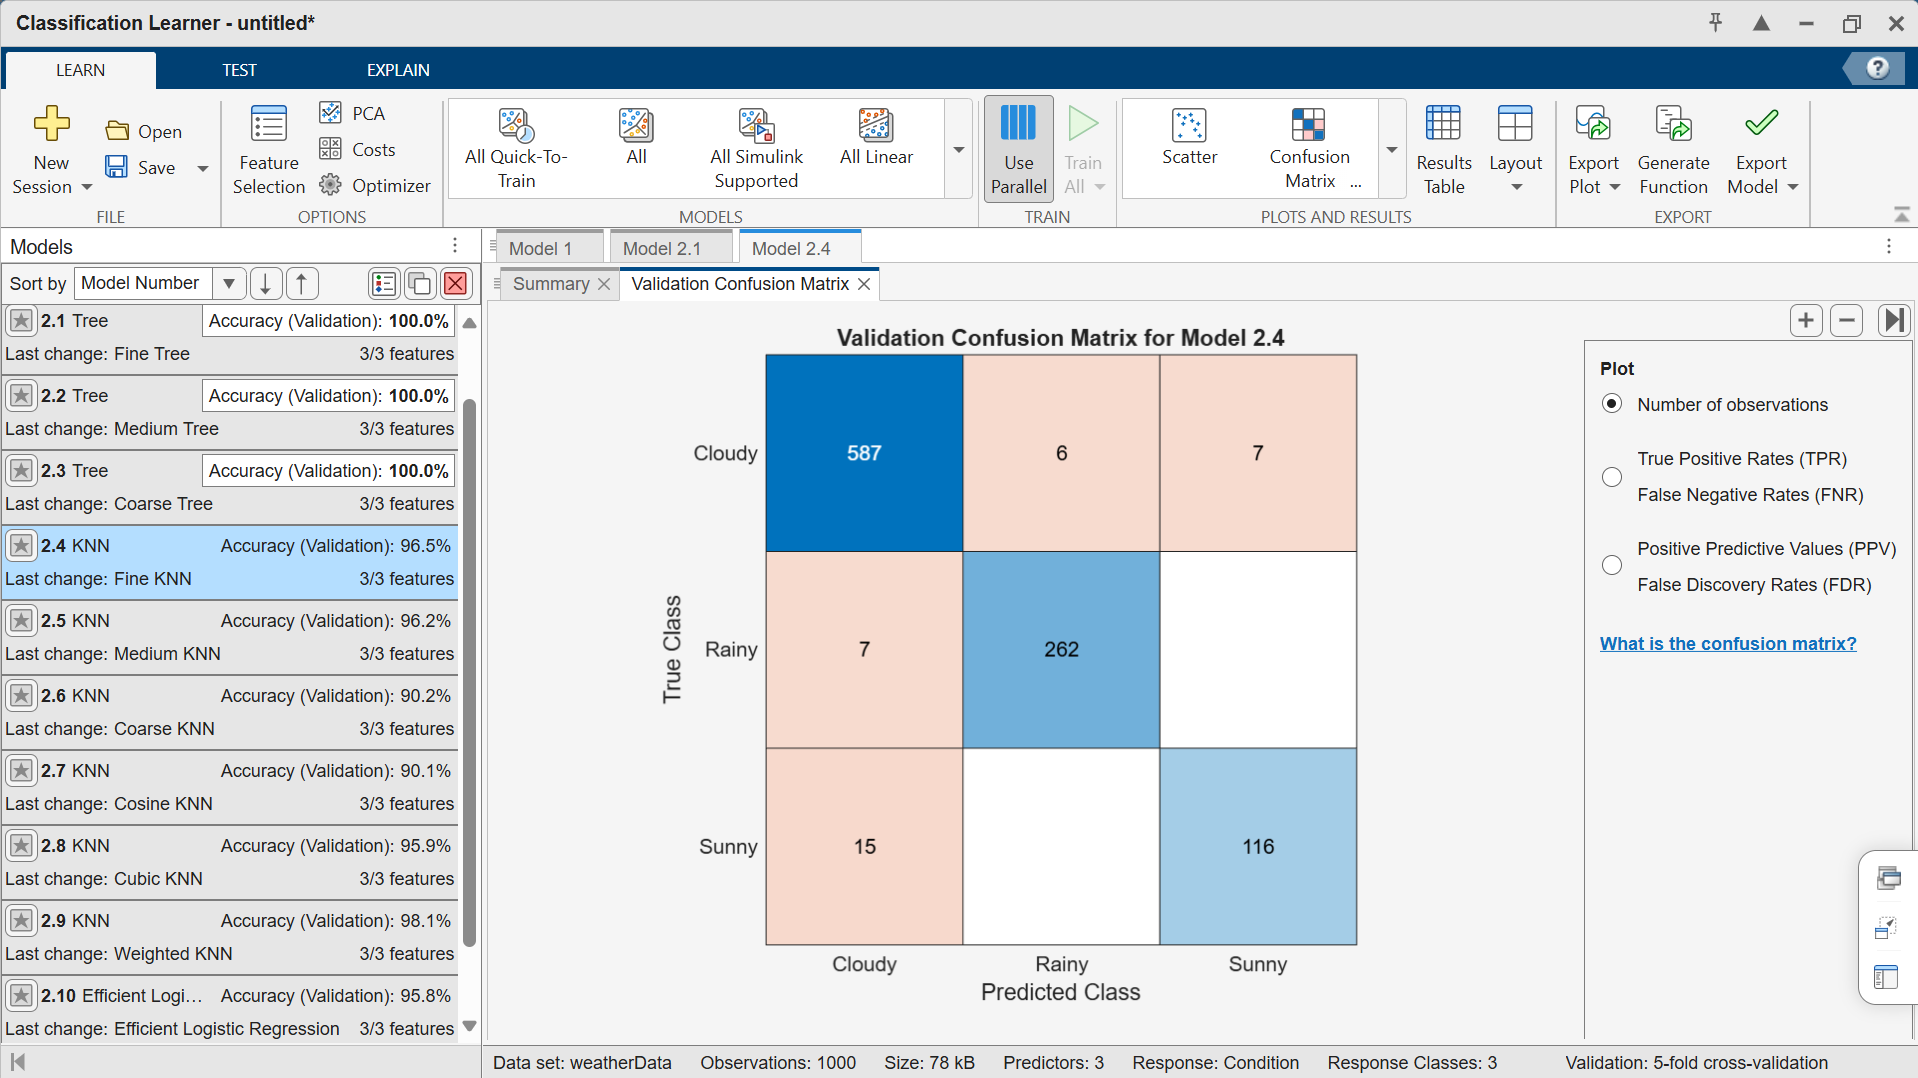

### Inference

load 2_Machine_Learning/trainedModel.mat
load 2_Machine_Learning/testData.mat
pred = trainedModel.predictFcn

Ypred = pred(testData)

Ypred =      3
     2
     2
     2
     3
     3
     3
     3
     2
     2


% confusionchart

Go further

classificationLearner("2_Machine_Learning/ClassificationLearnerSession.mat")